# SDI New Noise Running Randy's MM code multiple times to generate uncorrelated noise

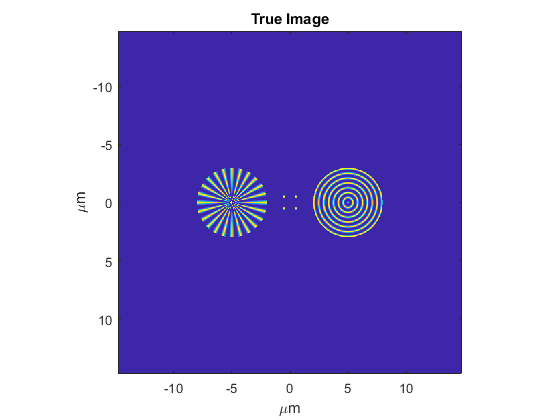

addpath("C:\Users\19709\Documents\MATLAB\Gabe_MATLAB\SPIFIandCHIRPTSims")
addpath("C:\Users\19709\Documents\MATLAB\Gabe_MATLAB\SDI\MPSFIFforSDI\NewSDIData")
clear variables
%load grids

x=load('xspatvec.mat');
x=x.Expression1;
fx=load('xspatfreq.mat');
fx=fx.Expression1;
y=load('yspatvec.mat');
y=y.Expression1;
fy=load('yspatfreq.mat');
fy=fy.Expression1;
trueimage=load("trueimage.mat");
trueimage=trueimage.Expression1;
figure; imagesc(x,y,trueimage)
xlabel('\mum')
ylabel('\mum')
axis square
title('True Image')

% Noise Free ones
for jj=1:4
    s=load(strcat('imgNF2',num2str(jj),'.mat'));
    imgNF2(:,:,jj)=s.Expression1;
end
for jj=1:6
    s=load(strcat('imgNF3',num2str(jj),'.mat'));
    imgNF3(:,:,jj)=s.Expression1;
end    
% Normalized Versions
for jj=1:4
    
    imgNF2N(:,:,jj)=Norm(imgNF2(:,:,jj));
end
for jj=1:6
    
    imgNF3N(:,:,jj)=Norm(imgNF3(:,:,jj));
end   

for jj=1:4
    s=load(strcat('OTF2',num2str(jj),'.mat'));
    OTF2(:,:,jj)=s.Expression1;
end
for jj=1:6
    s=load(strcat('OTF3',num2str(jj),'.mat'));
    OTF3(:,:,jj)=s.Expression1;
end    

Turn into PSFs (Above OTFs are not complex??)

for ii=1:4
    PSF2(:,:,ii)=abs(ifftshift(ifft2(OTF2(:,:,ii))));
end
for ii=1:6
    PSF3(:,:,ii)=abs(ifftshift(ifft2(OTF3(:,:,ii))));
end
% Normalized Versions
for ii=1:4
    PSF2N(:,:,ii)=Norm(PSF2(:,:,ii));
end
for ii=1:6
    PSF3N(:,:,ii)=Norm(PSF3(:,:,ii));
end

Implement own version of Randy's noise model

% Take 1d fft of object along x direction
f_x_Object=(fftshift(fft(trueimage,[],2),2));
% Take 1d fft of psfs along y direction
for ii=1:4
    f_y_PSF2(:,:,ii)=fftshift(fft(PSF2(:,:,ii),[],1),1);
end

for ii=1:6
    f_y_PSF3(:,:,ii)=fftshift(fft(PSF3(:,:,ii),[],1),1);
end

Load Signals

for jj=1:4
    s=load(strcat('Sig2',num2str(jj),'.mat'));
    Sig2(:,:,jj)=s.Expression1;
end

for jj=1:4
    s=load(strcat('Sig2',num2str(jj),'v2','.mat'));
    Sig2v2(:,:,jj)=s.Expression1;
end

for jj=1:4
    s=load(strcat('Sig2',num2str(jj),'v3','.mat'));
    Sig2v3(:,:,jj)=s.Expression1;
end

for ii=1:4
    sig2G(:,:,ii)=OTF2(:,:,ii).*f_x_Object;
end
for ii=1:4
    fftim2G(:,:,ii)=fftshift(abs(ifftshift(ifft(sig2G(:,:,ii),[],2),2)),2);
end

for jj=1:4
for ii=1:512
    OTF2x(ii,:,jj)=OTF2(end/2,:,jj);
end
end

for jj=1:6
for ii=1:512
    OTF3x(ii,:,jj)=OTF3(end/2,:,jj);
end
end

for jj=1:4
for ii=1:512
    OTF2yy(:,ii,jj)=OTF2(:,end/2,jj);
end
end

for jj=1:6
for ii=1:512
    OTF3yy(:,ii,jj)=OTF3(:,ii,jj);
end
end

for ii=1:4
    sig2Gx(:,:,ii)=OTF2x(:,:,ii).*f_x_Object;
end
for ii=1:4
    fftim2Gx(:,:,ii)=fftshift(abs(ifftshift(ifft(sig2Gx(:,:,ii),[],2),2)),2);
end

for ii=1:4
    sig2Gv2(:,:,ii)=((((OTF2(:,:,ii).*fftshift(fft2(fftim2Gx(:,:,ii)))))));
end

for ii=1:4
    sig2Gv3(:,:,ii)=ifft(((((OTF2yy(:,:,ii).*fftshift(fft(sig2Gx(:,:,ii),[],1),1))))),[],1);
end

for ii=1:4
    fftim2Gv2(:,:,ii)=(abs((ifft2(OTF2(:,:,ii).*fftshift(fft2(fftim2Gx(:,:,ii)))))));
end
for ii=1:4
    fftim2Gv3(:,:,ii)=conv_fft2(PSF2(:,:,ii),fftim2Gx(:,:,ii),'same');
end

for ii=1:6
    sig3Gx(:,:,ii)=OTF3x(:,:,ii).*f_x_Object;
end
for ii=1:6
    fftim3Gx(:,:,ii)=fftshift(abs(ifftshift(ifft(sig3Gx(:,:,ii),[],2),2)),2);
end

for ii=1:6
    sig3Gv2(:,:,ii)=((((OTF3(:,:,ii).*fftshift(fft2(fftim3Gx(:,:,ii)))))));
end

for ii=1:6
    sig3Gv3(:,:,ii)=ifft(((((OTF3yy(:,:,ii).*fftshift(fft(sig3Gx(:,:,ii),[],1),1))))),[],1);
end

for ii=1:6
    fftim3Gv2(:,:,ii)=(abs((ifft2(OTF3(:,:,ii).*fftshift(fft2(fftim3Gx(:,:,ii)))))));
end
for ii=1:6
    fftim3Gv3(:,:,ii)=conv_fft2(PSF3(:,:,ii),fftim3Gx(:,:,ii),'same');
end

for ii=1:6
    sig3G(:,:,ii)=OTF3(:,:,ii).*f_x_Object;
end
for ii=1:6
    fftim3G(:,:,ii)=fftshift(abs(ifftshift(ifft(sig3G(:,:,ii),[],2),2)),2);
end

Trying what seems like Randy's way

for ii=1:4
OTF2y(:,:,ii)=(fftshift(fft(PSF2(:,:,ii),[],1),1));
end

for ii=1:4
    sig2R(:,:,ii)=ifft(OTF2y(:,:,ii).*f_x_Object,[],1);
    
  
end


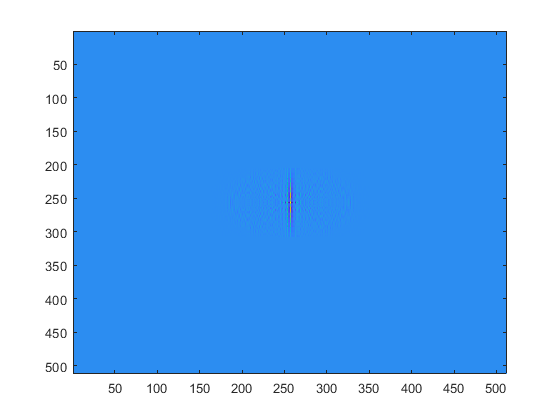

figure; imagesc(real(OTF2(:,:,4).*f_x_Object))

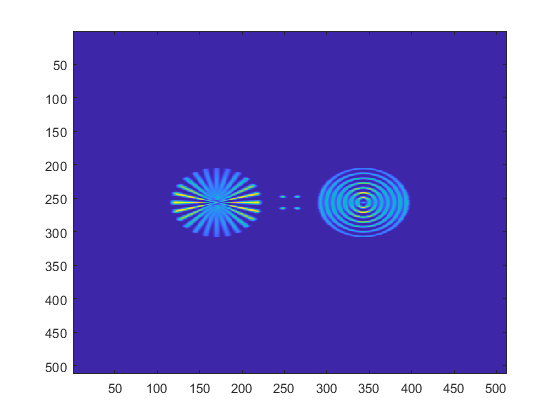

figure; imagesc(fftshift(abs(ifftshift(ifft(OTF2(:,:,4).*f_x_Object,[],2),2)),2))

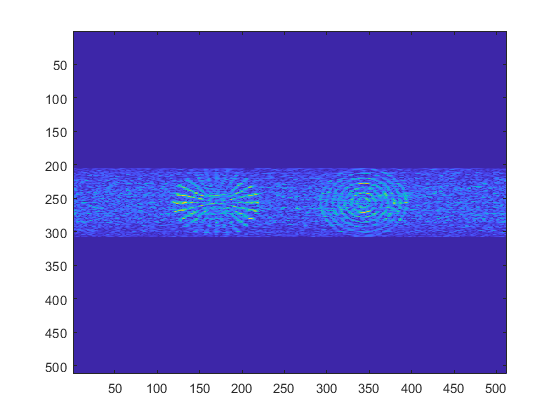

o1=max(max(abs(sig2G(:,:,1))));
o2=max(max(abs(sig2G(:,:,2))));
o3=max(max(abs(sig2G(:,:,3))));
o4=max(max(abs(sig2G(:,:,4))));
maxphtcnt=350;


Rsig21=real(sig2G(:,:,4));
Csig21=imag(sig2G(:,:,4));
Rpsig21=Rsig21;
Rpsig21(Rsig21<0)=0;
Rnsig21=-Rsig21;
Rnsig21(-Rsig21<0)=0;
Rpsig21n=poissrnd(Rpsig21*maxphtcnt/o1);
Rnsig21n=poissrnd(Rnsig21*maxphtcnt/o1);
Rsig21n=Rpsig21n-Rnsig21n;

Cpsig21=Csig21;
Cpsig21(Csig21<0)=0;
Cnsig21=-Csig21;
Cnsig21(-Csig21<0)=0;
Cpsig21n=poissrnd(Cpsig21*maxphtcnt/o1);
Cnsig21n=poissrnd(Cnsig21*maxphtcnt/o1);
Csig21n=Cpsig21n-Cnsig21n;

sig21n=Rsig21n+1i*Csig21n;
figure; imagesc(fftshift(abs(ifftshift(ifft(sig21n,[],2),2)),2))

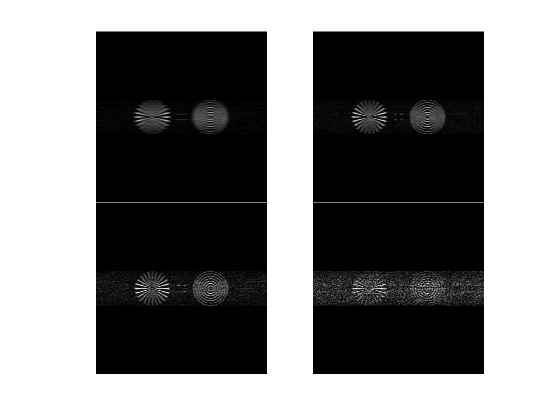

o1=max(max(abs(sig2G(:,:,1))));
maxphtcnt=350;
figure;

t=tiledlayout(2,2);
colormap gray
nexttile
imagesc(fftshift(abs(ifftshift(ifft(MPSpifiPoissNoise(sig2G(:,:,1),o1,maxphtcnt),[],2),2)),2))
axis square
axis off
nexttile
imagesc(fftshift(abs(ifftshift(ifft(MPSpifiPoissNoise(sig2G(:,:,2),o1,maxphtcnt),[],2),2)),2))
axis square
axis off
nexttile
imagesc(fftshift(abs(ifftshift(ifft(MPSpifiPoissNoise(sig2G(:,:,3),o1,maxphtcnt),[],2),2)),2))
axis square
axis off
nexttile
imagesc(fftshift(abs(ifftshift(ifft(MPSpifiPoissNoise(sig2G(:,:,4),o1,maxphtcnt),[],2),2)),2))
axis square
axis off
t.TileSpacing = 'none';

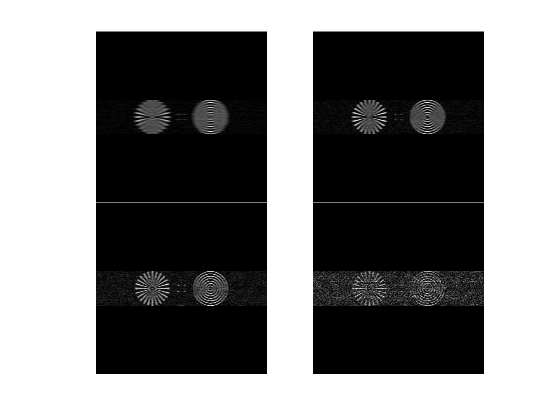

o1=max(max(abs(sig2Gx(:,:,1))));
maxphtcnt=350;
figure;

t=tiledlayout(2,2);
colormap gray
nexttile
imagesc(fftshift(abs(ifftshift(ifft(MPSpifiPoissNoise(sig2Gx(:,:,1),o1,maxphtcnt),[],2),2)),2))
axis square
axis off
nexttile
imagesc(fftshift(abs(ifftshift(ifft(MPSpifiPoissNoise(sig2Gx(:,:,2),o1,maxphtcnt),[],2),2)),2))
axis square
axis off
nexttile
imagesc(fftshift(abs(ifftshift(ifft(MPSpifiPoissNoise(sig2Gx(:,:,3),o1,maxphtcnt),[],2),2)),2))
axis square
axis off
nexttile
imagesc(fftshift(abs(ifftshift(ifft(MPSpifiPoissNoise(sig2Gx(:,:,4),o1,maxphtcnt),[],2),2)),2))
axis square
axis off
t.TileSpacing = 'none';

for ii=1:4
    imnoise2(:,:,ii)=fftshift(abs(ifftshift(ifft(MPSpifiPoissNoise(abs(sig2Gx(:,:,ii)),o1,maxphtcnt),[],2),2)),2)-fftshift(abs(ifftshift(ifft(abs(sig2Gx(:,:,ii))*maxphtcnt/o1,[],2),2)),2);
end

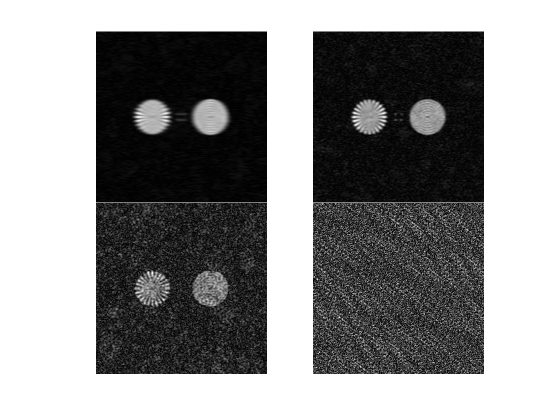

o1=max(max(abs(sig2Gv2(:,:,1))));
maxphtcnt=350;
figure;

t=tiledlayout(2,2);
colormap gray
nexttile
imagesc(fftshift(abs(ifftshift(ifft2(MPSpifiPoissNoise(sig2Gv2(:,:,1),o1,maxphtcnt))))))
axis square
axis off
nexttile
imagesc(fftshift(abs(ifftshift(ifft2(MPSpifiPoissNoise(sig2Gv2(:,:,2),o1,maxphtcnt))))))
axis square
axis off
nexttile
imagesc(fftshift(abs(ifftshift(ifft2(MPSpifiPoissNoise(sig2Gv2(:,:,3),o1,maxphtcnt))))))
axis square
axis off
nexttile
imagesc(fftshift(abs(ifftshift(ifft2(MPSpifiPoissNoise(sig2Gv2(:,:,4),o1,maxphtcnt))))))
axis square
axis off
t.TileSpacing = 'none';

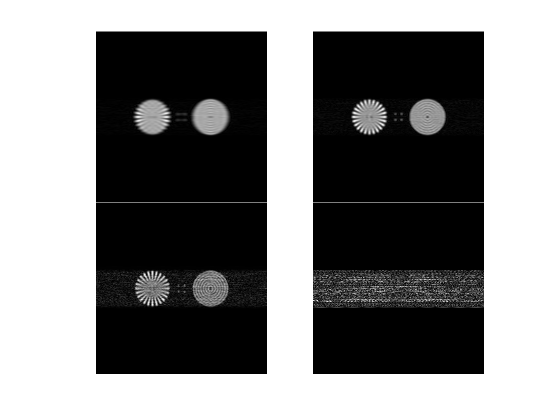

o1=max(max(abs(sig2Gv3(:,:,1))));
maxphtcnt=2550;
figure;

t=tiledlayout(2,2);
colormap gray
nexttile
imagesc(fftshift(abs(ifftshift(ifft(MPSpifiPoissNoise(sig2Gv3(:,:,1),o1,maxphtcnt),[],2),2)),2))
axis square
axis off
nexttile
imagesc(fftshift(abs(ifftshift(ifft(MPSpifiPoissNoise(sig2Gv3(:,:,2),o1,maxphtcnt),[],2),2)),2))
axis square
axis off
nexttile
imagesc(fftshift(abs(ifftshift(ifft(MPSpifiPoissNoise(sig2Gv3(:,:,3),o1,maxphtcnt),[],2),2)),2))
axis square
axis off
nexttile
imagesc(fftshift(abs(ifftshift(ifft(MPSpifiPoissNoise(sig2Gv3(:,:,4),o1,maxphtcnt),[],2),2)),2))
axis square
axis off
t.TileSpacing = 'none';

There we go this one is working!! The trick is to cut off spatial frequencies in fx using OTF and then BLUR THE TIME TRACES in the Y-direction without forgetting to ifft back in y. Still getting some weird noise for the last order...(Fixed by going to higher photon count now matches Randy's level.

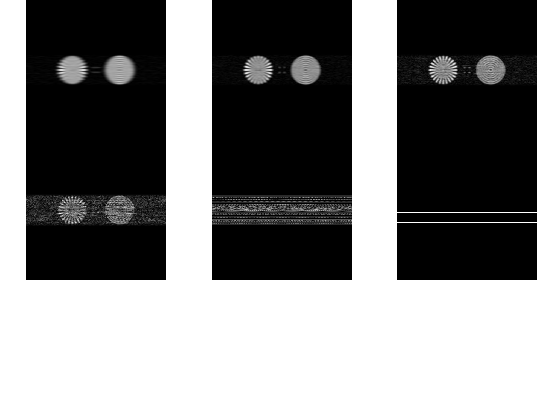

o1=max(max(mean(real(sum(sig3Gv3,3)+9),2)));
%o1=max(max(abs(sig3Gv3(:,:,1))));
maxphtcnt=255000;
figure;

tiledlayout(3,3,"TileSpacing","none","Padding","tight");
colormap gray
nexttile
imagesc(fftshift(abs(ifftshift(ifft(MPSpifiPoissNoise(sig3Gv3(:,:,1),o1,maxphtcnt),[],2),2)),2))
axis square
axis off
nexttile
imagesc(fftshift(abs(ifftshift(ifft(MPSpifiPoissNoise(sig3Gv3(:,:,2),o1,maxphtcnt),[],2),2)),2))
axis square
axis off
nexttile
imagesc(fftshift(abs(ifftshift(ifft(MPSpifiPoissNoise(sig3Gv3(:,:,3),o1,maxphtcnt),[],2),2)),2))
axis square
axis off
nexttile
imagesc(fftshift(abs(ifftshift(ifft(MPSpifiPoissNoise(sig3Gv3(:,:,4),o1,maxphtcnt),[],2),2)),2))
axis square
axis off
nexttile
imagesc(fftshift(abs(ifftshift(ifft(MPSpifiPoissNoise(sig3Gv3(:,:,5),o1,maxphtcnt),[],2),2)),2))
axis square
axis off
nexttile
imagesc(fftshift(abs(ifftshift(ifft(MPSpifiPoissNoise(sig3Gv3(:,:,6),o1,maxphtcnt),[],2),2)),2))
axis square
axis off

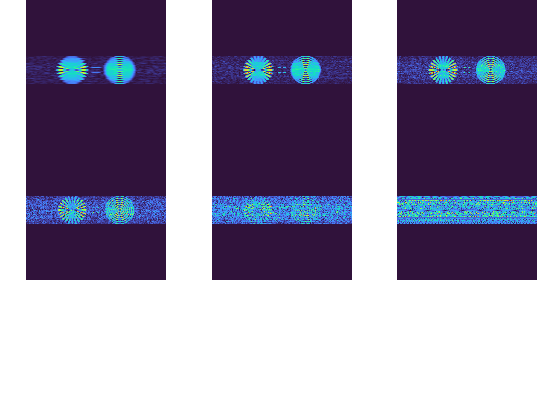

o1=max(max(abs(sig3G(:,:,1))));
maxphtcnt=350;
figure;

tiledlayout(3,3,"TileSpacing","none","Padding","tight");
colormap Turbo
nexttile
imagesc(fftshift(abs(ifftshift(ifft(MPSpifiPoissNoise(sig3G(:,:,1),o1,maxphtcnt),[],2),2)),2))
axis square
axis off
nexttile
imagesc(fftshift(abs(ifftshift(ifft(MPSpifiPoissNoise(sig3G(:,:,2),o1,maxphtcnt),[],2),2)),2))
axis square
axis off
nexttile
imagesc(fftshift(abs(ifftshift(ifft(MPSpifiPoissNoise(sig3G(:,:,3),o1,maxphtcnt),[],2),2)),2))
axis square
axis off
nexttile
imagesc(fftshift(abs(ifftshift(ifft(MPSpifiPoissNoise(sig3G(:,:,4),o1,maxphtcnt),[],2),2)),2))
axis square
axis off
nexttile
imagesc(fftshift(abs(ifftshift(ifft(MPSpifiPoissNoise(sig3G(:,:,5),o1,maxphtcnt),[],2),2)),2))
axis square
axis off
nexttile
imagesc(fftshift(abs(ifftshift(ifft(MPSpifiPoissNoise(sig3G(:,:,6),o1,maxphtcnt),[],2),2)),2))
axis square
axis off

% t.TileSpacing = 'none';
% t.Padding = 'tight';

## Noisy Images the correct way

%o1=max(max(abs(sig2Gv3(:,:,1))));
o1=max(max(mean(real(sum(sig3Gv3,3)+9),2)));
maxphtcnt=255000;
for ii=1:4
    imNG2(:,:,ii)=fftshift(abs(ifftshift(ifft(MPSpifiPoissNoise(sig2Gv3(:,:,ii),o1,maxphtcnt),[],2),2)),2);
end
o1=max(max(abs(sig3Gv3(:,:,1))));
%maxphtcnt=2550;
for ii=1:6
    imNG3(:,:,ii)=fftshift(abs(ifftshift(ifft(MPSpifiPoissNoise(sig3Gv3(:,:,ii),o1,maxphtcnt),[],2),2)),2);
end

Noise Free

for ii=1:4
    imNFG2(:,:,ii)=fftshift(abs(ifftshift(ifft(sig2Gv3(:,:,ii),[],2),2)),2);
end
% o1=max(max(abs(sig3Gv3(:,:,1))));
% maxphtcnt=2550;
for ii=1:6
    imNFG3(:,:,ii)=fftshift(abs(ifftshift(ifft(sig3Gv3(:,:,ii),[],2),2)),2);
end

Extract Noise

%o1=max(max(abs(sig2Gv3(:,:,1))));
o1=max(max(mean(real(sum(sig2Gv3,3)+9),2)));
for ii=1:4
    G2N(:,:,ii)=imNG2(:,:,ii)-imNFG2(:,:,ii)*maxphtcnt/o1;
end
%o1=max(max(abs(sig3Gv3(:,:,1))));
o1=max(max(mean(real(sum(sig3Gv3,3)+9),2)));
for ii=1:6
    G3N(:,:,ii)=imNG3(:,:,ii)-imNFG3(:,:,ii)*maxphtcnt/o1;
end

%o1=max(max(abs(sig3Gv3(:,:,1))));
o1=max(max(mean(real(sum(sig3Gv3,3)+9),2)));
for ii=1:6
imNG3v2(:,:,ii)=G3N(:,:,ii)+imNFG3(:,:,ii)*maxphtcnt/o1;
end

for ii=1:6
    imNG3N(:,:,ii)=Norm(imNG3(:,:,ii));
end
for ii=1:6
    imNG3Nv2(:,:,ii)=Norm(imNG3v2(:,:,ii));
end

s=size(PSF3N);
delta=zeros(size(trueimage));
delta(end/2,end/2)=1;
param2=reshape(PSF3N,[s(1) s(1)*s(3)]);%OBBB2;
Imdata=reshape(imNG3Nv2,[s(1) s(1)*s(3)]);
bdn=circshift(circshift(conv_fft2(Imdata,delta),1,2),1,1);
%bdn=conv_fft2(param2,Norm(trueimage));
% bdn2=imnoise(Norm(conv_fft2(reshape(psft2camf,[s(1) s(1)*length(dcSAX)]),Norm(Im))),'gaussian',.01,.0001);
Ac2=@(vin,transp_flag) Cnv2Dns(vin,param2,transp_flag,s(1)^2,size(bdn));%,size(obbb),size(obbb));%,size(obbb),size(obbb));
%Ac1=@(vin,transp_flag) Cnv2D(vin,param1,transp_flag);%,length(psf2(:)),size(b3));
tic;
miter=100;
k=1:miter;
%for i=1:5
[X4 info3]=IRfista(Ac2,bdn(:),k,struct('x0','none', 'MaxIter',miter, 'x_true',trueimage(:), ...
    'NoiseLevel','none', 'eta',1.01, 'NE_Rtol',1e-12, 'IterBar','on', ...
    'NoStop','off', 'RegParam',.001, 'xMin',0, 'xMax',inf, 'xEnergy','none'));

Reached maximum number of iterations


%end
toc;

Elapsed time is 138.438927 seconds.


clear recMPIMN3 errorrecrecMPIMN3
recMPIMN3=reshape(X4,[s(1) s(1) miter]);
min(info3.NE_Rnrm);
for ii=1:size(recMPIMN3,3)
    errorrecrecMPIMN3(ii)=immse(Norm(trueimage(200:311,112:400)),Norm(recMPIMN3(200:311,112:400,ii)));
end

[eval locm]=min(errorrecrecMPIMN3);
eval

eval = 0.0312

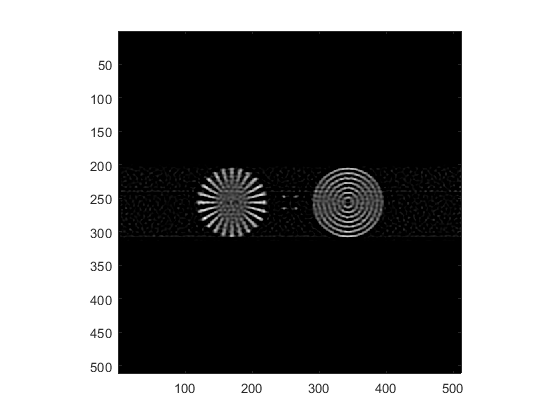

figure; imagesc(recMPIMN3(:,:,locm))
axis square
colormap gray